clc
clear

# **Projeto Final - Circuitos Elétricos II**

## **Circuito no Regime Permanente Senoidal**

**Grupo 07:**

- Miguel Marques Ferreira - 20180080112

- Pedro Henrique Garcia - 20190112775

- Maria Stefanie Moura - 20180085530

- Gabriel Bordini Lira - 20180092570

## Dados de Entrada

dados_entrada = readtable('./data/tabela_de_entrada_grupo_07_c2.csv')

dados_entrada = 3×14 table
    Ramo    n_Sa_da    n_Chegada    R_Ohm_    L_H_    I0_A_    C_F_    V0_V_    Tipo_Fonte_de_Tens_o    Vind_V_    Fase_V_rad_    Iind_A_    Fase_I_rad_    W_rad_s_
    ____    _______    _________    ______    ____    _____    ____    _____    ____________________    _______    ___________    _______    ___________    ________

     1         1           2          2          0      0       0        0               0                10            0            0            0            8    
 

%dados_entrada = readtable('./tabela_de_entrada _senoidal_vitor.xcsv')
%dados_entrada = load("circuito_anotacoes_garcia.mat")
%dados_entrada = dados_entrada.dados_entrada

### Informações

#### Número de Ramos

numero_de_ramos = size(dados_entrada.Ramo);
numero_de_ramos = numero_de_ramos(1)

numero_de_ramos = 3

#### Número de Nós

aux1 = max(dados_entrada.n_Sa_da);
aux2 = max(dados_entrada.n_Chegada);

if aux1 > aux2
    numero_de_nos = aux1(1);
else
    numero_de_nos = aux2(1);
end

numero_de_nos

numero_de_nos = 2

#### Colunas do Arquivo (número e nome da coluna)

- Ramo

- Nó de Saída

- Nó de Entrada

- Resistência de Ramo

- Indutância de Ramo

- Corrente Inicial do Indutor

- Capacitância de Ramo

- Tensão Inicial do Capacitor

- Tipo de Fonte (não é utilizado)

- Fonte de Tensão de Ramo

- Fase da Fonte de Tensão de Ramo

- Fonte de Corrente de Ramo

- Fase da Fonte de Corrente de Ramo

- Frequência Angular

## Formando as Matrizes

### Matriz de Incidência

matriz_de_incidencia = zeros(numero_de_nos,numero_de_ramos);
entrada_e_saida = dados_entrada(:,(2:3));
entrada_e_saida;
for row = 1:numero_de_ramos
    
    %saida = entrada_e_saida(row,:).(1);
    entrada_saida = entrada_e_saida(row,:);
    %entrada = entrada_e_saida(row,:).(2);
    matriz_de_incidencia(entrada_saida.(1),row) = 1;
    matriz_de_incidencia(entrada_saida.(2),row) = -1;
    
end

matriz_de_incidencia

matriz_de_incidencia =      1     1     1
    -1    -1    -1


matriz_de_incidencia_T = transpose(matriz_de_incidencia)

matriz_de_incidencia_T =      1    -1
     1    -1
     1    -1


### Matriz de Incidência Reduzida

matriz_de_incidencia_red = matriz_de_incidencia((1:(end-1)),:);
matriz_de_incidencia_red_T = transpose(matriz_de_incidencia_red)

matriz_de_incidencia_red_T =      1
     1
     1


### Matriz de Admitâncias

matriz_de_admitancias = zeros(numero_de_ramos,numero_de_ramos);

frequencia_angular = max(dados_entrada.W_rad_s_);

resistencias_s = dados_entrada.R_Ohm_;
capacitancias = dados_entrada.C_F_;
indutancias = dados_entrada.L_H_;

% Laplace
capacitancias_s = 1./(1i*frequencia_angular.*capacitancias);
capacitancias_s(capacitancias_s(:) == Inf) = 0 %tratando a exceção de divisão por zero e adicionando...

capacitancias_s =      0
     0
     0


% zero caso o elemento passado seja nulo.
indutancias_s = 1i*frequencia_angular.*indutancias

indutancias_s =    0.0000 + 0.0000i
   0.0000 + 2.0000i
   0.0000 + 2.0000i


impedancia_equivalente = resistencias_s + indutancias_s + capacitancias_s

impedancia_equivalente =    2.0000 + 0.0000i
   1.0000 + 2.0000i
   4.0000 + 2.0000i


admitancias = 1./impedancia_equivalente;
matriz_de_admitancias = diag(admitancias)

matriz_de_admitancias =    0.5000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.2000 - 0.4000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2000 - 0.1000i


### Yn - Admitância de Nó

Yn = (matriz_de_incidencia_red*matriz_de_admitancias)*matriz_de_incidencia_red_T

Yn = 0.9000 - 0.5000i

%n = Yn((1:end-1),(1:end-1))

### Vs - Fontes de Tensão Independentes

Vs = dados_entrada.Vind_V_.*cos(deg2rad(dados_entrada.Fase_V_rad_)) + 1i.*dados_entrada.Vind_V_.*sin(deg2rad(dados_entrada.Fase_V_rad_))

Vs =     10
     0
     0


### Js - Fontes de Corrente Independentes

Js = dados_entrada.Iind_A_.*cos(deg2rad(dados_entrada.Fase_I_rad_)) + 1i.*dados_entrada.Iind_A_.*sin(deg2rad(dados_entrada.Fase_I_rad_))

Js =      0
     0
     0


### Is - Correntes

Is = (matriz_de_incidencia_red*matriz_de_admitancias)*Vs - matriz_de_incidencia_red*Js

Is = 5

%Is = Is((1:end-1),:)

### e - Tensão de Nó

e = inv(Yn)*Is

e = 4.2453 + 2.3585i

%m_a = matriz_de_incidencia_red*(-1);
%E = ((m_a*Js)+ (((matriz_de_incidencia_red*matriz_de_admitancias)*Vs)))/Yn

### V - Tensão de Ramo

V = matriz_de_incidencia_red_T*e

V =    4.2453 + 2.3585i
   4.2453 + 2.3585i
   4.2453 + 2.3585i


### J - Corrente de Ramo

J = Js + matriz_de_admitancias*V - matriz_de_admitancias*Vs

J =   -2.8774 + 1.1792i
   1.7925 - 1.2264i
   1.0849 + 0.0472i


## Gerando Tabela de Saída

if size(e) == 1
    aux3 = zeros(numero_de_ramos,1);
    aux3 = aux3+e
end

aux3 =    4.2453 + 2.3585i
   4.2453 + 2.3585i
   4.2453 + 2.3585i


tabela_final = table(V, aux3, J,'VariableNames',{'Tensão de Ramo (V)' 'Tensão de Nó (V)' 'Corrente de Ramo (A)'}) %compass (representação de fasores no matlab)

tabela_final = 3×3 table
    Tensão de Ramo (V)    Tensão de Nó (V)    Corrente de Ramo (A)
    __________________    ________________    ____________________

      4.2453+2.3585i       4.2453+2.3585i       -2.8774+1.1792i   
      4.2453+2.3585i       4.2453+2.3585i        1.7925-1.2264i   
      4.2453+2.3585i       4.2453+2.3585i        1.0849+0.04717i  


tabela_final

tabela_final = 3×3 table
    Tensão de Ramo (V)    Tensão de Nó (V)    Corrente de Ramo (A)
    __________________    ________________    ____________________

      4.2453+2.3585i       4.2453+2.3585i       -2.8774+1.1792i   
      4.2453+2.3585i       4.2453+2.3585i        1.7925-1.2264i   
      4.2453+2.3585i       4.2453+2.3585i        1.0849+0.04717i  


### Gráfico

Ramo = 1

Ramo = 1

### Fasor

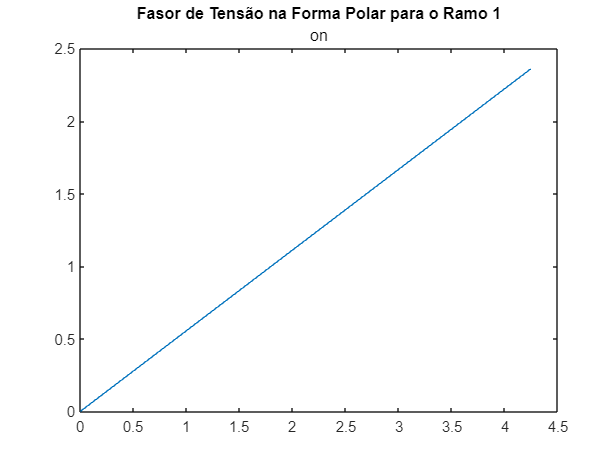

plot([0 real(V(Ramo))],[0 imag(V(Ramo))]);
title 'Fasor de Tensão na Forma Polar para o Ramo 1' on;

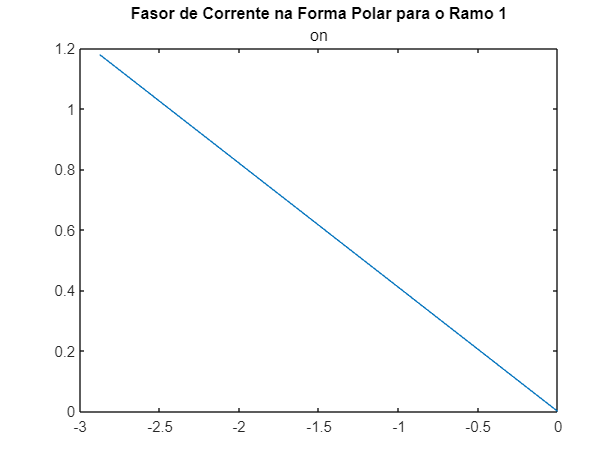

plot([0 real(J(Ramo))],[0 imag(J(Ramo))]);
title 'Fasor de Corrente na Forma Polar para o Ramo 1' on;